% Load CSV data
[frame, xx] = obtainframedata(1716, 1724, "Both_10.10.10.66_%d.csv");

on frame number1
on frame number2
on frame number3
on frame number4
on frame number5
on frame number6
on frame number7
on frame number8
on frame number9


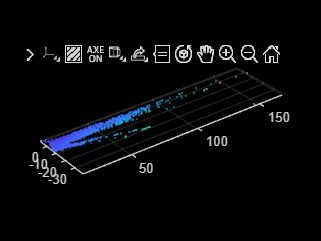

measurement =   -7.4728e-03
   1.9782e-02
   9.9978e-01
   2.1224e+00


parameter_estimate =   -3.2025e-07
   8.9558e-06
   1.0000e+00
   2.0722e+00


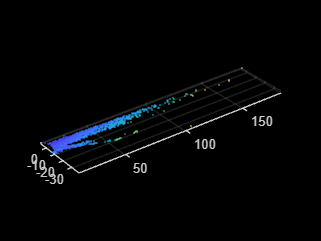

measurement =   -7.5794e-03
   2.2396e-02
   9.9972e-01
   2.0803e+00


parameter_estimate =   -6.4505e-07
   1.9091e-05
   1.0000e+00
   2.0770e+00


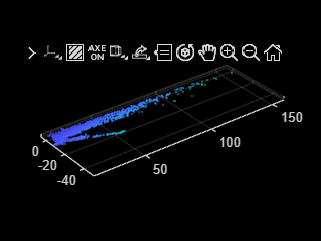

measurement =   -6.7116e-03
   2.0720e-02
   9.9976e-01
   2.0533e+00


parameter_estimate =   -9.3265e-07
   2.8463e-05
   1.0000e+00
   2.0630e+00


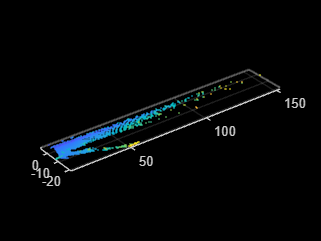

measurement =   -4.3138e-03
   2.4038e-02
   9.9970e-01
   2.0179e+00


parameter_estimate =   -1.1175e-06
   3.9332e-05
   1.0000e+00
   2.0364e+00


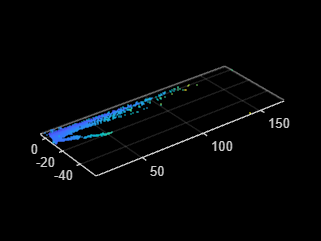

measurement =   -3.8053e-03
   5.8066e-03
   9.9998e-01
   2.0342e+00


parameter_estimate =   -1.2805e-06
   4.1943e-05
   1.0000e+00
   2.0351e+00


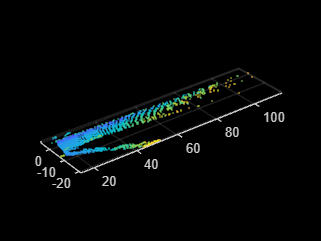

measurement =   -1.6880e-03
   9.9774e-03
   9.9995e-01
   1.9697e+00


parameter_estimate =   -1.3528e-06
   4.6441e-05
   1.0000e+00
   1.9966e+00


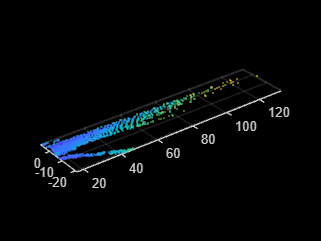

measurement =   -5.2466e-03
   1.8298e-03
   9.9998e-01
   2.0166e+00


parameter_estimate =   -1.5776e-06
   4.7249e-05
   1.0000e+00
   2.0084e+00


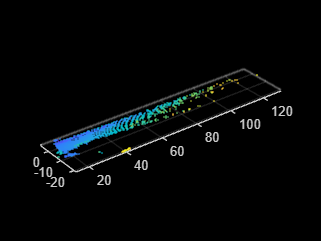

measurement =   -5.0633e-03
   2.2518e-02
   9.9973e-01
   2.0270e+00


parameter_estimate =   -1.7945e-06
   5.7422e-05
   1.0000e+00
   2.0194e+00


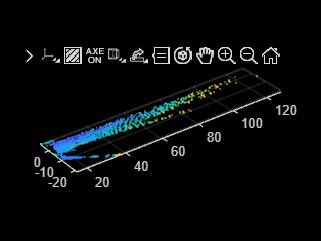

measurement =   -3.4336e-03
   1.0604e-02
   9.9994e-01
   1.9650e+00


parameter_estimate =   -1.9416e-06
   6.2196e-05
   1.0000e+00
   1.9873e+00


[xyz,xyz_road] = spherical2cartesian(frame);

parameter_estimate = [0; 0; 1; 2];  % initial parameter estimate [a; b; c; d]

% loop over frames 
for fr = 1:length(frame)

    data = xyz{fr}(:,1:3); 
    pc = pointCloud(data);
    
    % Kalman Filter parameters
    % These need to be modified
    R = eye(4)*0.1;  % measurement noise covariance
    P = diag([4.2857e-06 4.5293e-05 2.4581e-09 1.4370e-01]);  % estimate error covariance
    
    % This function uses the M-estimator SAmple Consensus (MSAC) algorithm to find the plane
    % MSAC algorithm is a variant of the RANdom SAmple Consensus (RANSAC) algorithm.
    [model, inlierIndices] = pcfitplane(pc, 0.2, [0, 0, 1], 10);  % adjust distanceThreshold as necessary
    plane1 = select(pc,inlierIndices);
    figure(fr)
    pcshow(plane1)
    measurement = model.Parameters'
    
    % Prediction step
    % prior 
    parameter_prediction = parameter_estimate;
    P_minus = P;
    
    % Update step
    % posterior 
    K = P_minus/(P_minus + R); % Kalman Gain
    meas_err = (measurement - sensor_model(C*p_predict)); % measurement error
    parameter_estimate = parameter_prediction + K*meas_err
end 


% Final plane parameters [a; b; c; d] are in 'parameter_estimate'

